## Example Curve Fitting: Least-squares minimization

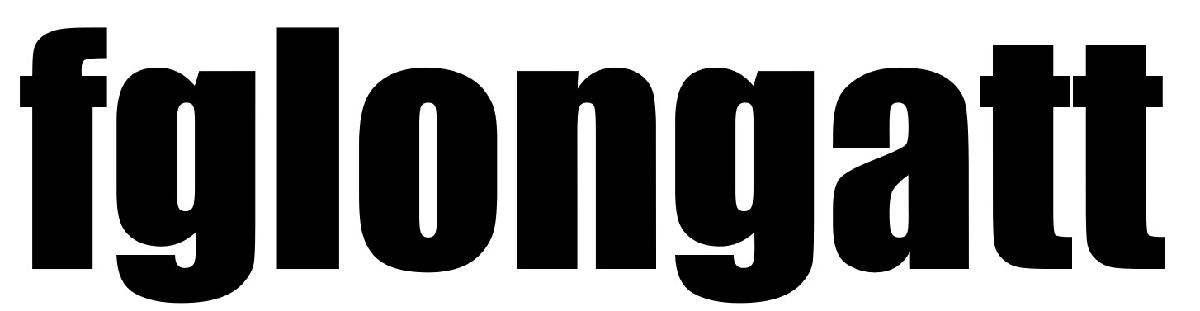  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

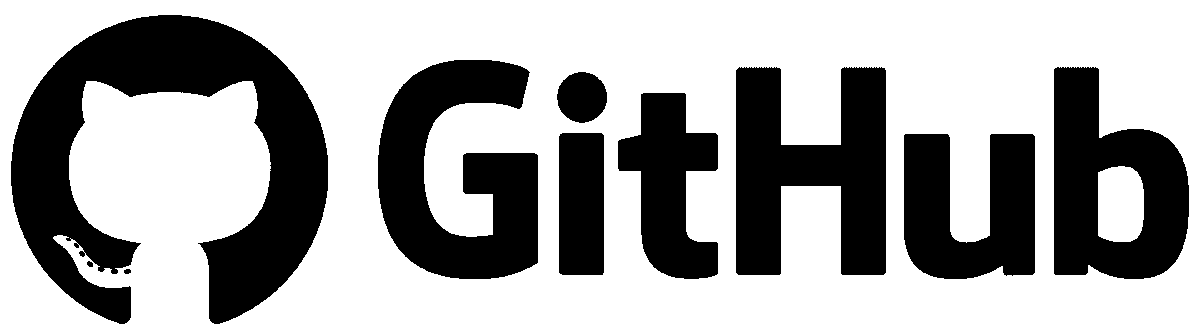 [https://github.com/fglongatt](https://github.com/fglongatt) 

Consider the following data $\left(x,y\right)$:

clc
clear 
x = [0.0 0.25 0.78 1.10 1.59 2.32];
y = [1.25 1.0288 0.70840 0.582871 0.45392 0.348273]

y =     1.2500    1.0288    0.7084    0.5829    0.4539    0.3483


Fit a curve of the form:


$$y\left(x\right)=\alpha_1 +\alpha_2 e^{-x}$$


### Solution

Plotting raw data:

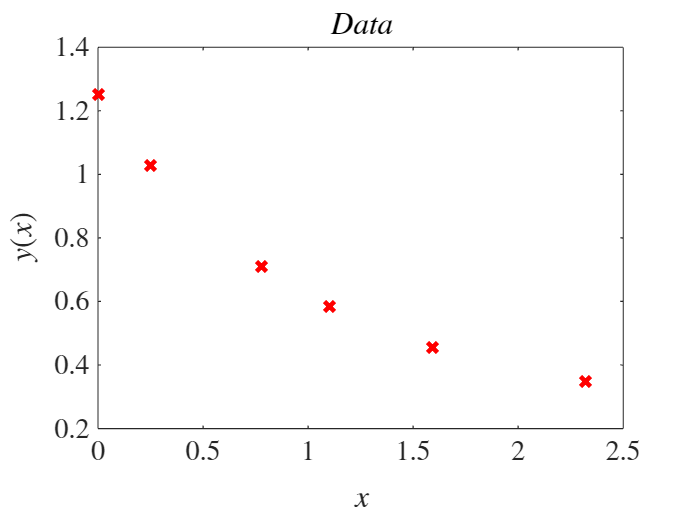

plot(x,y,'Xr','LineWidth',2);
xlabel('$x$','Interpreter','latex')
ylabel('$y(x)$','Interpreter','latex')
title_latex = ['$Data$'];
title(title_latex,'Interpreter','latex')
set(gca,"fontsize",12);
set(gca,'TickLabelInterpreter','latex')

**Step 1:** Define the parameters in terms of one variable $\mathbf{x}=\left\lbrack \begin{array}{cc}
x_1  & x_2 
\end{array}\right\rbrack$:

$\mathbf{x}=\left\lbrack \begin{array}{cc}
x_1  & x_2 
\end{array}\right\rbrack$ where ${x_1 =\alpha }_1$ ${x_2 =\alpha }_2$

**Step 2:**Define the curve as a function of the parameters $\mathbf{x}$ and the data raw $\left\lbrace x_i ,y_i \right\rbrace$:

F = @(x,xdata)x(1) + x(2)*exp(-xdata);

**Step 3:**Arbitrarily set initial point ${\mathbf{x}}_0$ as follows:

x0 = [0.5 1];

**Step 4:**Run the solver and plot the resulting fit.

[xsol,resnorm,~,exitflag,output] = lsqcurvefit(F,x0,x,y)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xsol =     0.2500    1.0000


resnorm = 3.5509e-11

exitflag = 1

output = struct with fields:
      firstorderopt: 5.9736e-14
         iterations: 1
          funcCount: 6
       cgiterations: 0
          algorithm: 'trust-region-reflective'
           stepsize: 0.2500
            message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 5.973595e-14,↵is less than options.OptimalityTolerance = 1.000000e-06.'
       bestfeasible: []
    constrviolation: []


Printing solution:

fprintf(' Solution: ')

 Solution: 

fprintf('  α1 = %4.4f',xsol(1))

  α1 = 0.2500

fprintf('  α2 = %4.4f',xsol(2))

  α2 = 1.0000

Plotting

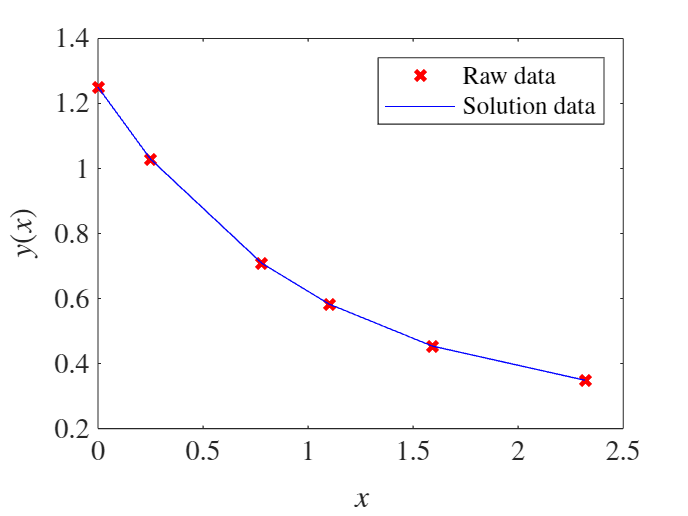

a1 = 0.25;
a2 = 1;
ysol = a1 + a2 * exp(-x);
plot(x,y,'Xr','LineWidth',2);
hold on
plot(x,ysol,'-b','LineWidth',0.2);
xlabel('$x$','Interpreter','latex')
ylabel('$y(x)$','Interpreter','latex')
% title_latex = ['$Data$'];
%title(title_latex,'Interpreter','latex')
set(gca,"fontsize",12);
legend({'Raw data','Solution data'},'Interpreter','latex')
set(gca,'TickLabelInterpreter','latex')

Be part of our community 

 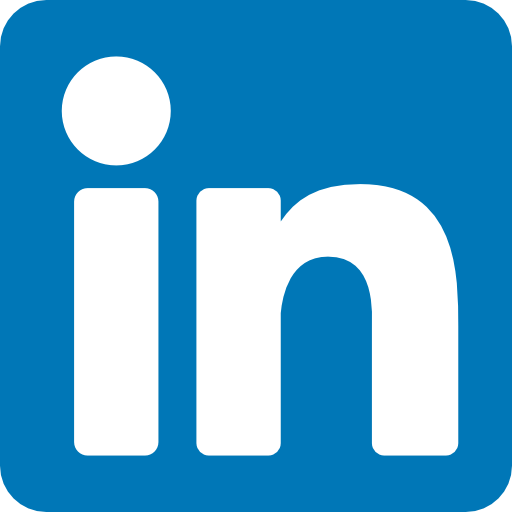 [https://www.linkedin.com/in/francisco-gonzalez-longatt/](https://www.linkedin.com/in/francisco-gonzalez-longatt/) 

 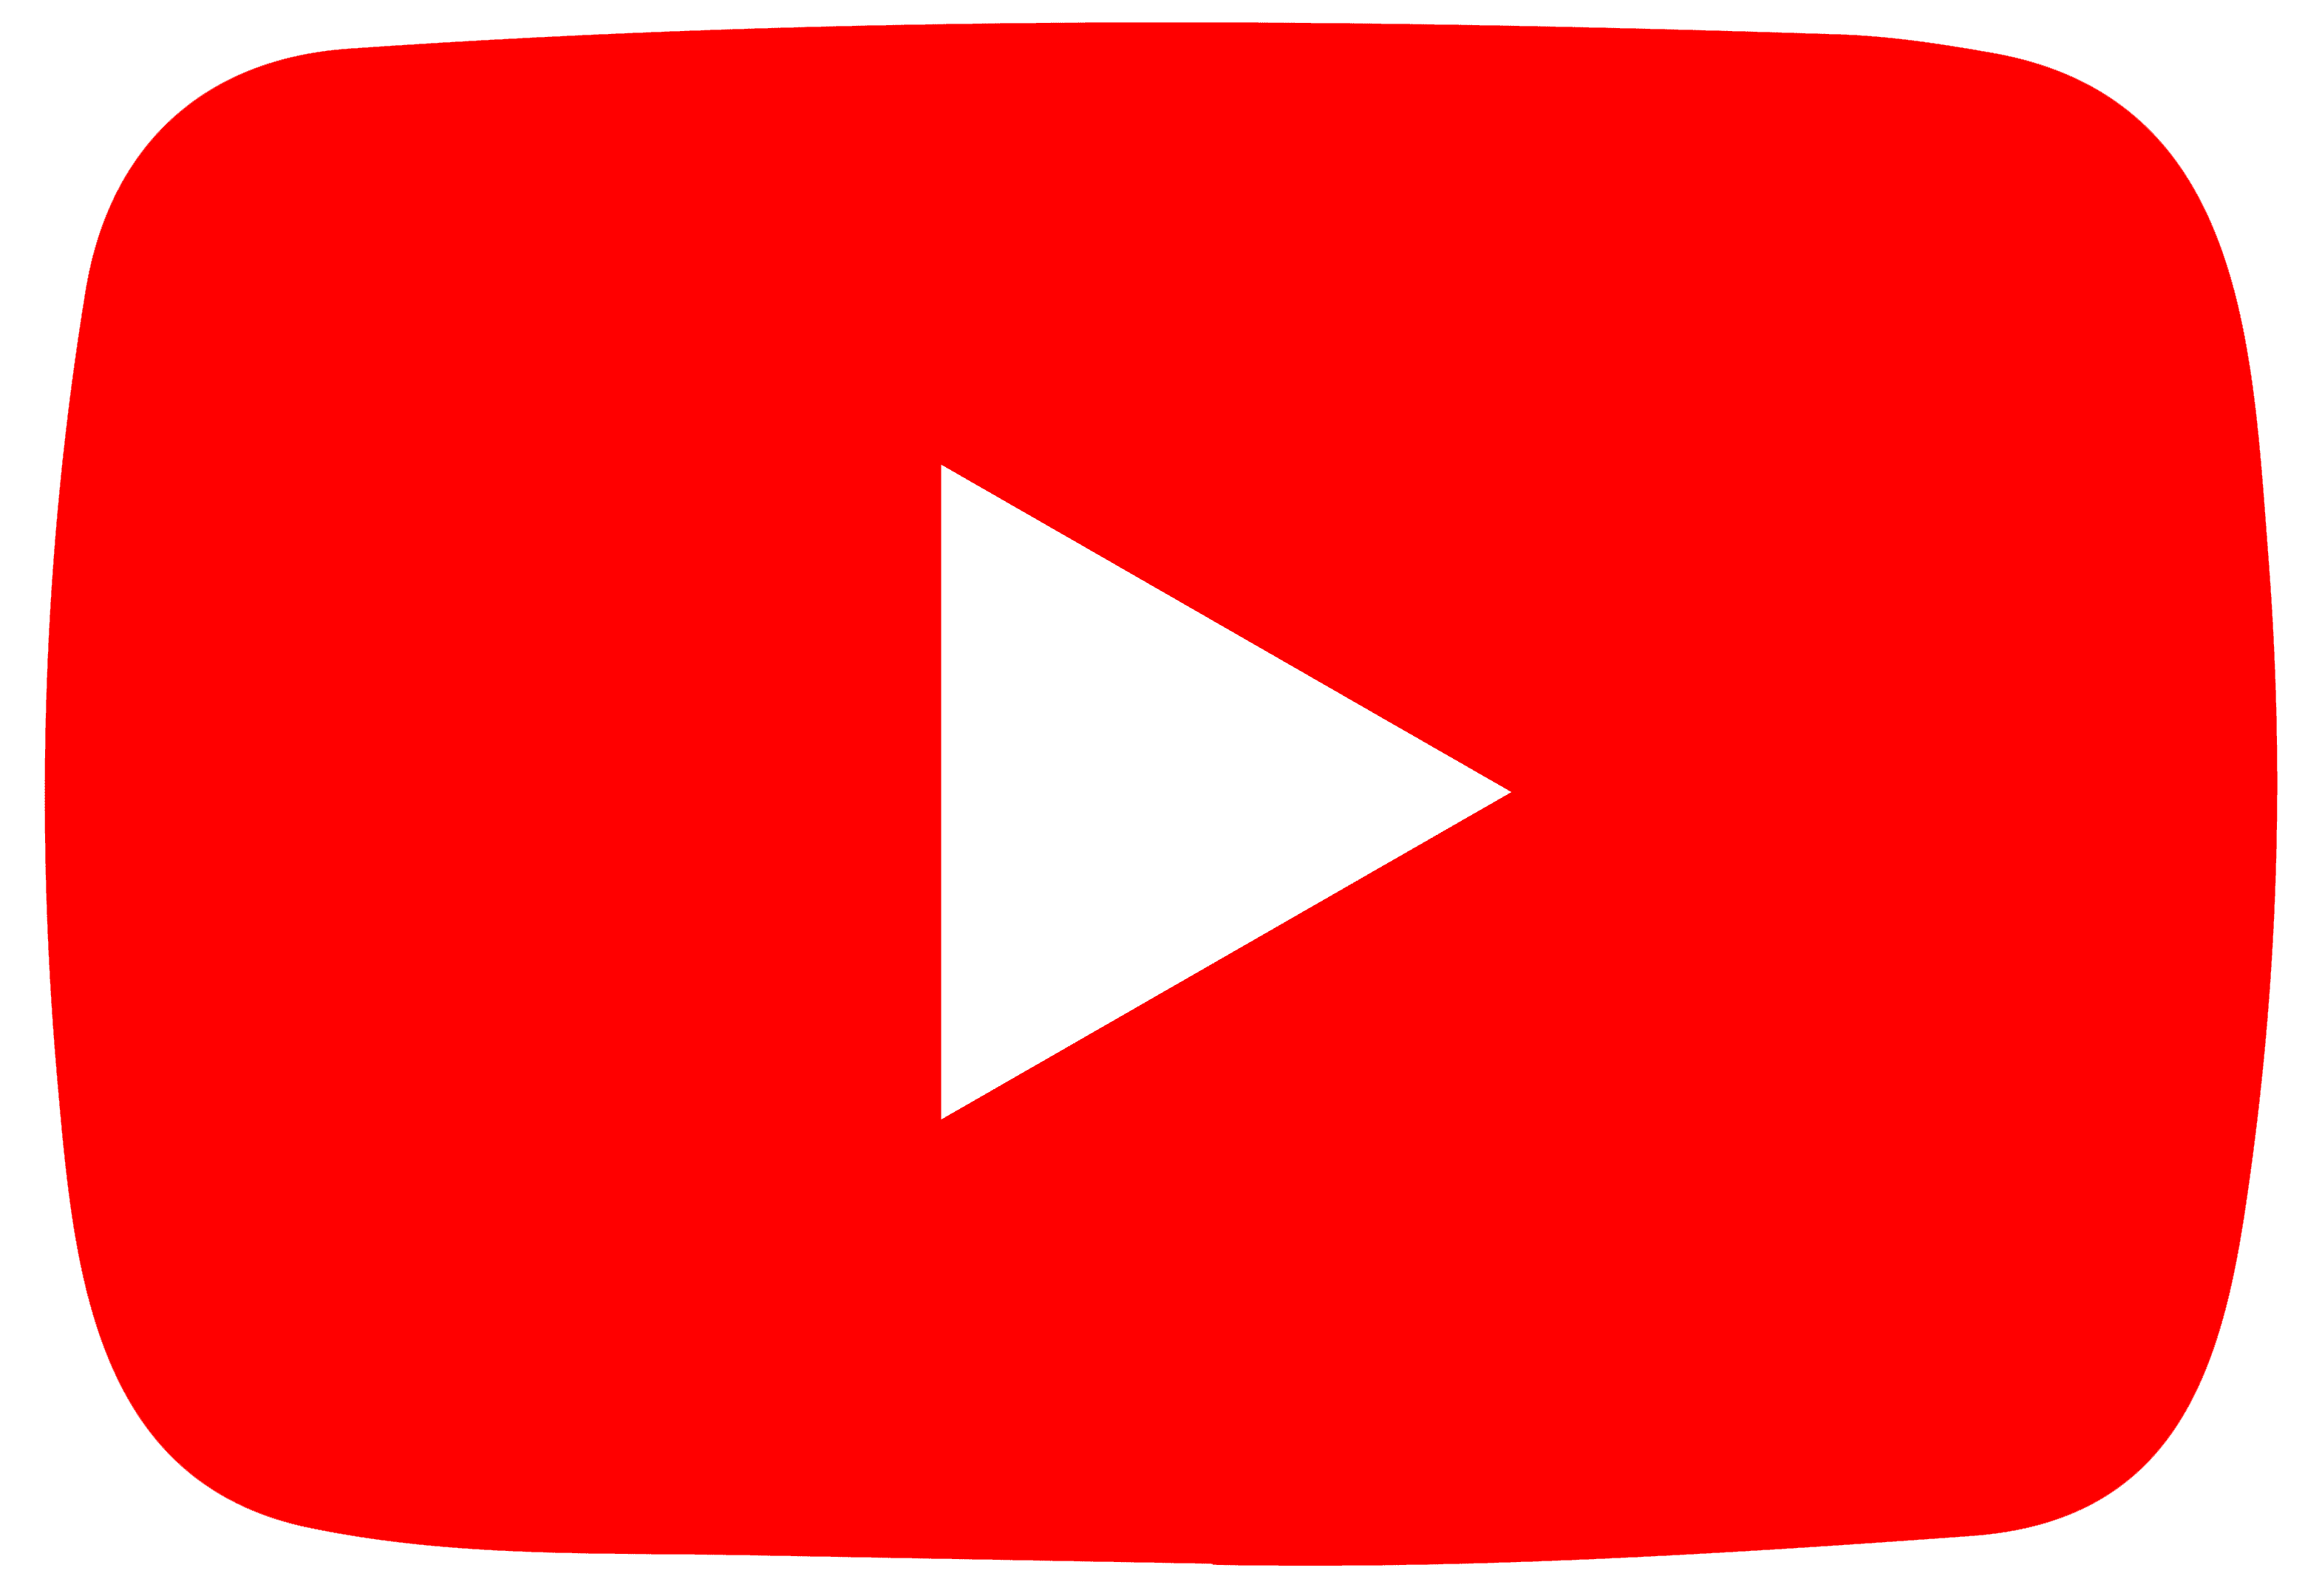 [https://www.youtube.com/user/fmglongatt](https://www.youtube.com/user/fmglongatt) 

 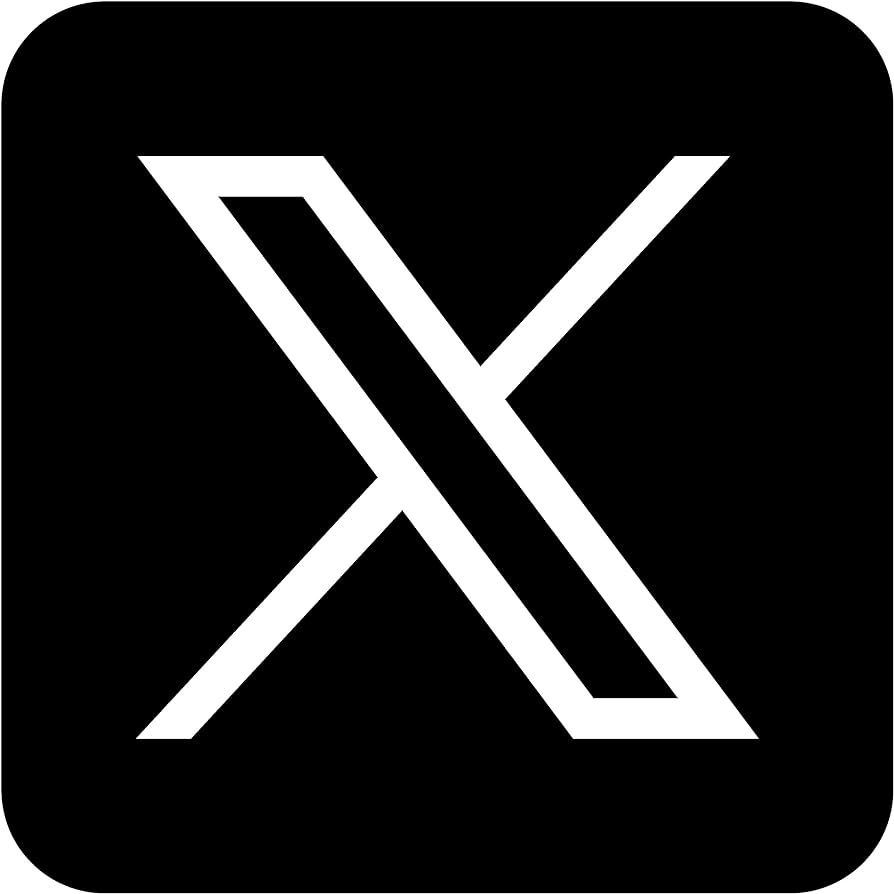  [https://twitter.com/fglongatt](https://twitter.com/fglongatt) 

 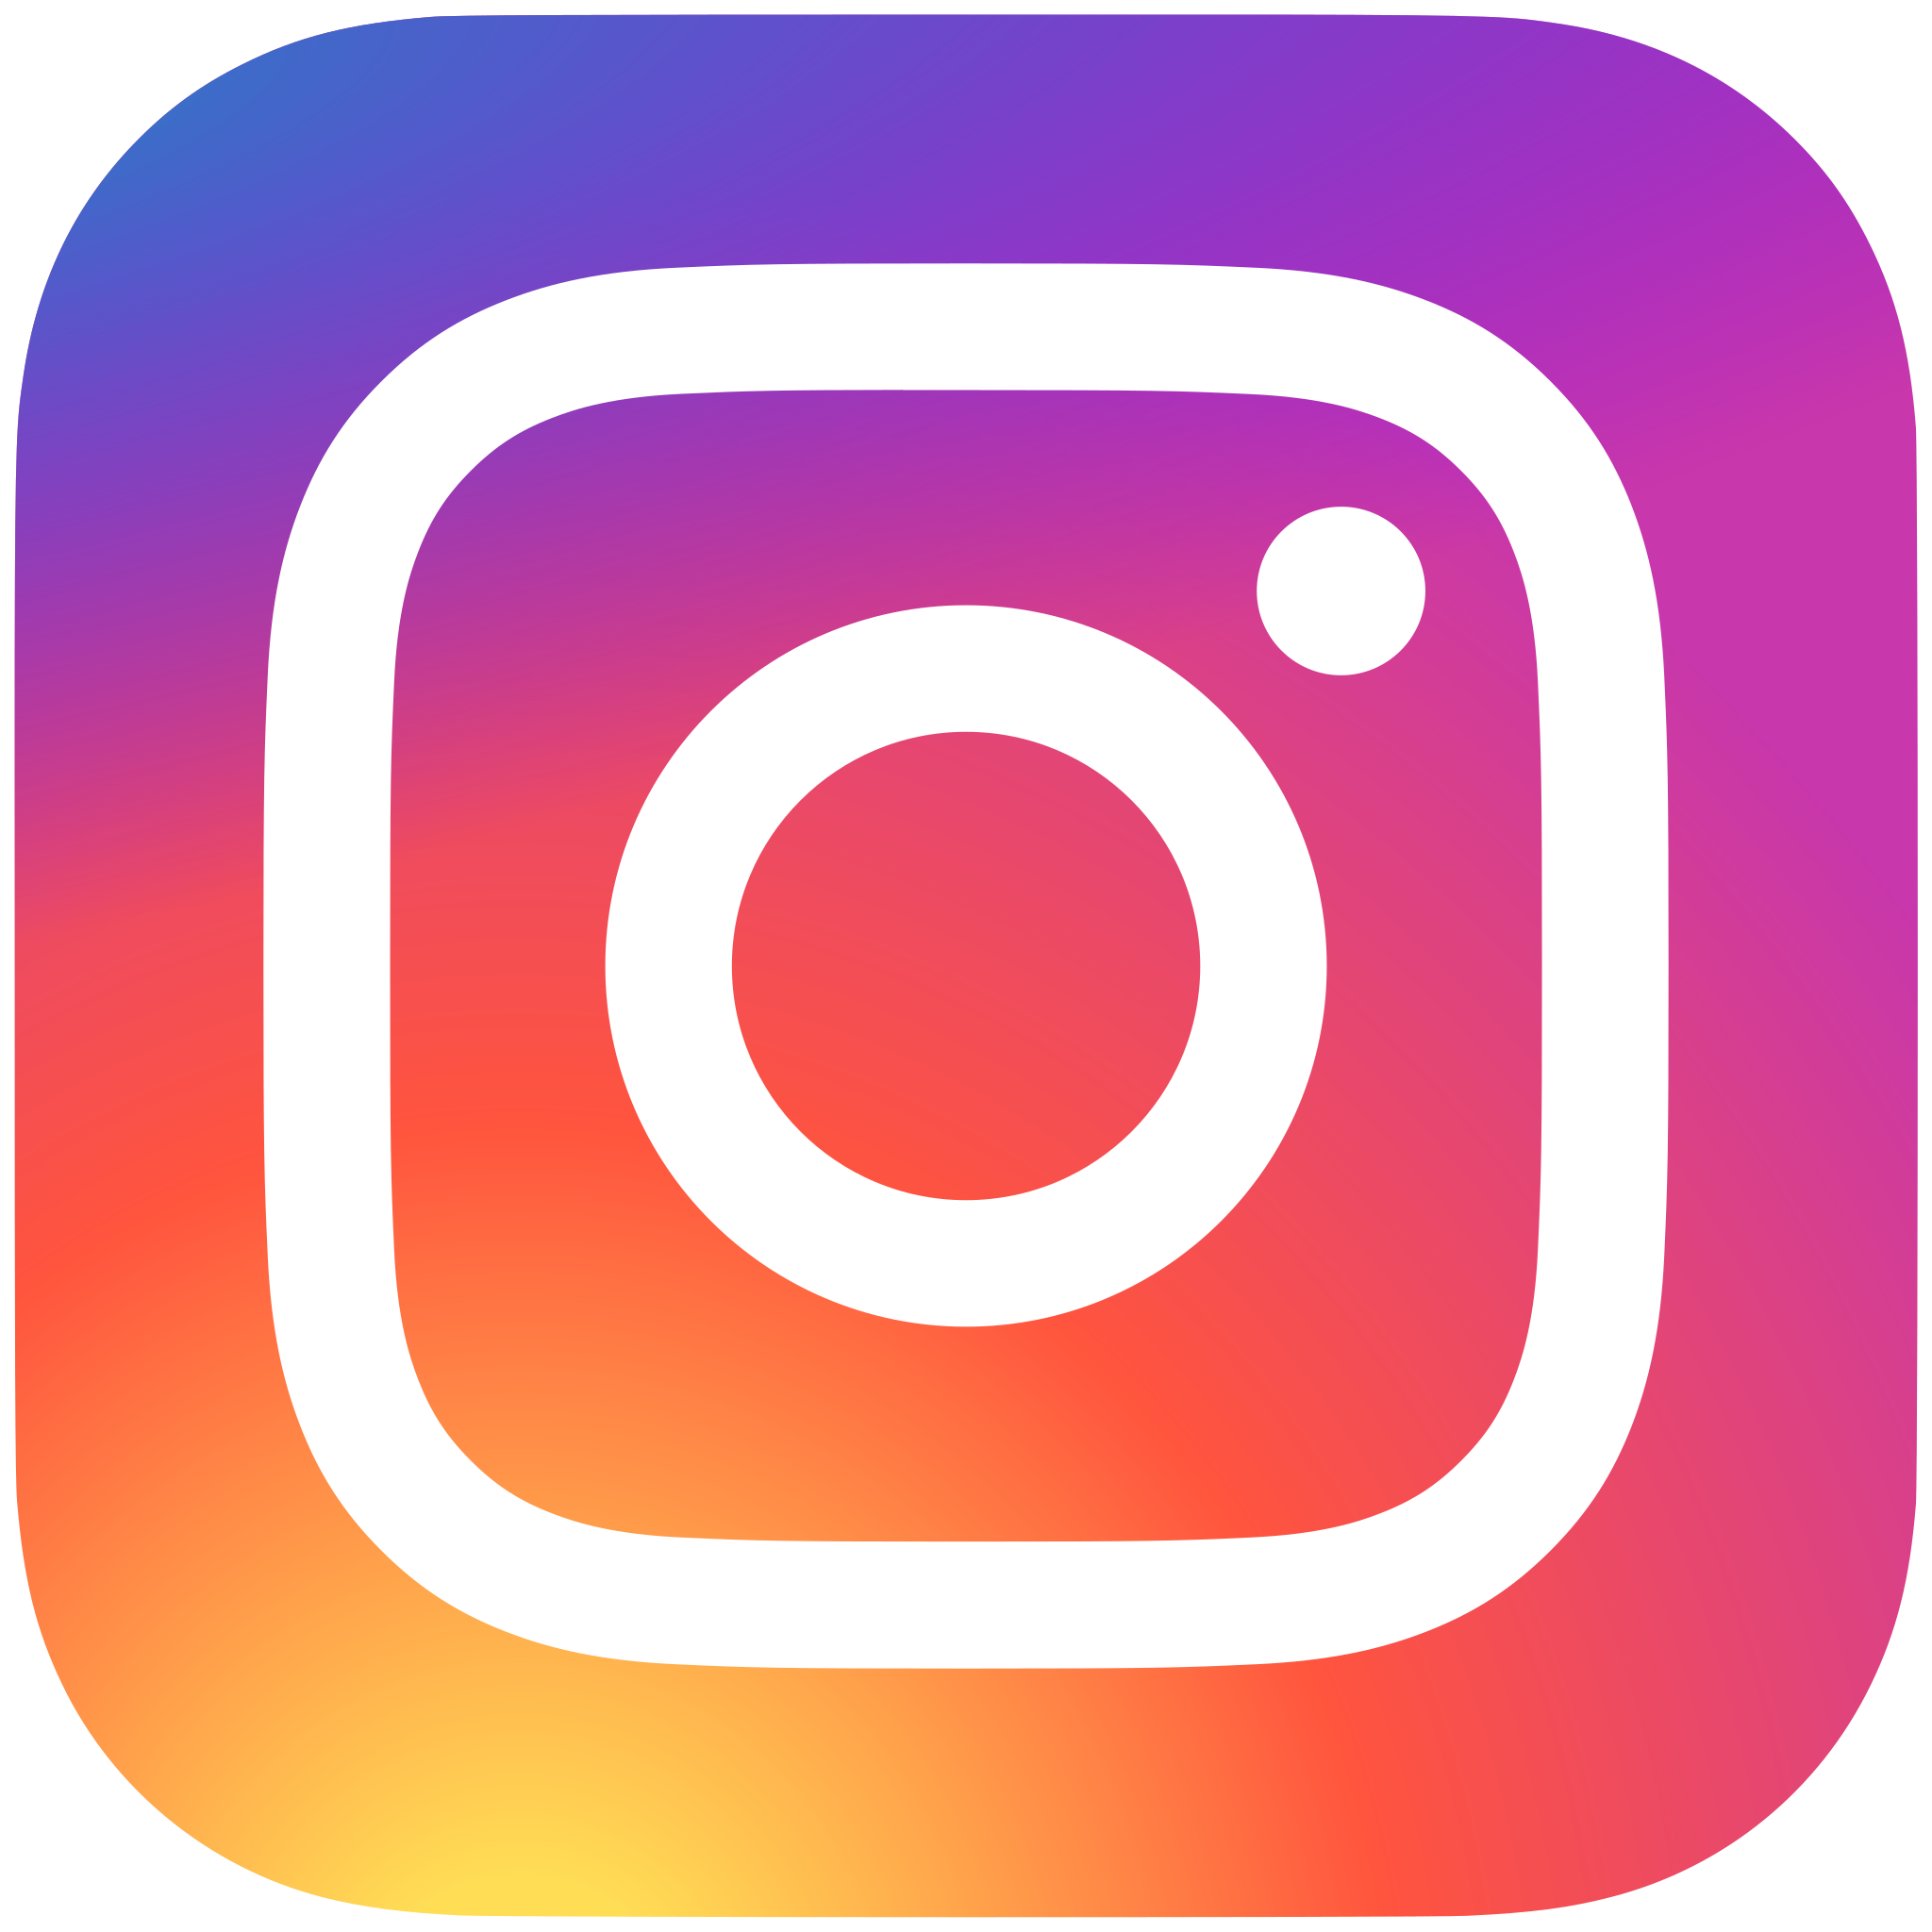 [https://www.instagram.com/fglongatt/](https://www.instagram.com/fglongatt/) 